# **HW6 Program Assignment**

**By: 105060012 張育菘**

## P1

Consider again the inverse DFT given in (8.2).

$x\left\lbrack n\right\rbrack =\frac{1}{N}\sum_{k=0}^{N-1} X\left\lbrack k\right\rbrack W_N^{-\textrm{kn}} ,\;n=0,1,\ldotp \ldotp \ldotp ,N-1$ (8.2)

(a) Replace k by ${\left\langle -k\right\rangle }_N$ in (8.2) and show that the resulting summation is a DFT expression, that is, $\mathrm{IDFT}\left\lbrace X\left\lbrack k\right\rbrack \right\rbrace =\frac{1}{N}\mathrm{DFT}\left\lbrace X\left\lbrack {\left\langle -k\right\rangle }_N \right\rbrack \right\rbrace$.

Ans.


$$\textrm{IDFT}\left\lbrace X\left\lbrack k\right\rbrack \right\rbrace =x\left\lbrack n\right\rbrack =\frac{1}{N}\sum_{k=0}^{N-1} X\left\lbrack k\right\rbrack W_N^{-\textrm{kn}}$$



$$\textrm{DFT}\left\lbrace X\left\lbrack {\left\langle -k\right\rangle }_N \right\rbrack \right\rbrace =\sum_{k=0}^{N-1} X\left\lbrack {\left\langle -k\right\rangle }_N \right\rbrack W_N^{\textrm{kn}} =\sum_{k=0}^{N-1} X\left\lbrack k\right\rbrack W_N^{-\textrm{kn}}$$



$$\Longrightarrow \textrm{IDFT}\left\lbrace X\left\lbrack k\right\rbrack \right\rbrace =\frac{1}{N}\sum_{k=0}^{N-1} X\left\lbrack k\right\rbrack W_N^{-\textrm{kn}} =\frac{1}{N}\textrm{DFT}\left\lbrace X\left\lbrack {\left\langle -k\right\rangle }_N \right\rbrack \right\rbrace$$


(b) Develop a MATLAB function x = IDFT(X,N) using the fft function that uses the above approach. Verify your function on signal x[n] = {1, 2, 3, 4, 5, 6, 7, 8}. 

close all; clear;
fprintf('1(b)\n');

1(b)



open IDFT.m;

x = [1 2 3 4 5 6 7 8]

x =      1     2     3     4     5     6     7     8


X = fft(x); N = length(X);
x_verify = IDFT(X, N)

x_verify =      1     2     3     4     5     6     7     8


(Comment)

由上面的結果顯示，從自己設計的 IDFT 把經由 fft 轉換得到的 X 轉回去 time domain 的 x_verify 與原本的 x 相同。

## P2

In this problem we will investigate differences in the speeds of DFT and FFT algorithms when stored twiddle factors are used. 

$\left\lbrack \begin{array}{c}
X\left\lbrack 0\right\rbrack \\
X\left\lbrack 1\right\rbrack \\
X\left\lbrack 2\right\rbrack \\
X\left\lbrack 3\right\rbrack \\
X\left\lbrack 4\right\rbrack \\
X\left\lbrack 5\right\rbrack \\
X\left\lbrack 6\right\rbrack \\
X\left\lbrack 7\right\rbrack 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccccccc}
1 & 1 & 1 & 1 & 1 & 1 & 1 & 1\\
1 & W_8  & W_8^2  & W_8^3  & W_8^4  & W_8^5  & W_8^6  & W_8^7 \\
1 & W_8^2  & W_8^4  & W_8^6  & 1 & W_8^2  & W_8^4  & W_8^6 \\
1 & W_8^3  & W_8^6  & W_8^{1\;}  & W_8^4  & W_8^7  & W_8^2  & W_8^5 \\
1 & W_8^4  & 1 & W_8^4  & 1 & W_8^4  & 1 & W_8^4 \\
1 & W_8^5  & W_8^2  & W_8^7  & W_8^4  & W_8  & W_8^6  & W_8^3 \\
1 & W_8^6  & W_8^4  & W_8^2  & 1 & W_8^6  & W_8^4  & W_8^2 \\
1 & W_8^7  & W_8^6  & W_8^5  & W_8^4  & W_8^3  & W_8^2  & W_8 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\left\lbrack 0\right\rbrack \\
x\left\lbrack 1\right\rbrack \\
x\left\lbrack 2\right\rbrack \\
x\left\lbrack 3\right\rbrack \\
x\left\lbrack 4\right\rbrack \\
x\left\lbrack 5\right\rbrack \\
x\left\lbrack 6\right\rbrack \\
x\left\lbrack 7\right\rbrack 
\end{array}\right\rbrack$  (8.8)

(a) Write a function W = dft_matrix(N) that computes the DFT matrix $W_N$ given in (8.8).

Ans.

$W_N =e^{-j\frac{2\pi }{N}}$ , ${\left(W_N \right)}_{\left(n+1\right)\times \left(m+1\right)} ={\left(e^{-j\frac{2\pi }{N}} \right)}^{nm} ,\;n,m=0,1,\ldotp \ldotp \ldotp ,N-1$

close all; clear;
fprintf('2(a)\n');

2(a)


open dft_matrix.m;

(b) Write a function X = dftdirect_m(x,W) that modifies the dftdirect function using the matrix W from (a). Using the tic and toc functions compare computation times for the dftdirect and dftdirect_m function for N = 128, 256, 512, and 1024. For this purpose generate an N-point complex-valued signal as x = randn(1,N) + 1j*randn(1,N). (verify your code with fft first) 

close all; clear;
fprintf('2(b)\n');

2(b)



open dftdirect_m.m;

N_set = [128 256 512 1024];
for i = 1:1:length(N_set)
    fprintf('N = %d\n', N_set(i));
    x = randn(1,N_set(i)) + 1j*randn(1,N_set(i));
    
    fprintf('  by dftdirect_m\n');
    tic;
    W = dft_matrix(N_set(i));
    X1 = dftdirect_m(x, W)
    toc;
    
    fprintf('  by dftdirect\n');
    tic; 
    X2 = dftdirect(x)
    toc;
end

N = 128


  by dftdirect_m


X1 =   14.8600 -16.9911i   9.9053 -18.4707i  12.4703 - 8.8463i -11.5983 -11.2830i -18.1389 +16.5774i  -8.3138 - 1.3829i  13.9919 -14.7572i  -8.3491 - 3.5470i  -6.6867 + 3.1268i -16.2774 + 0.8017i -16.4445 + 4.0810i  10.8502 + 8.8029i  -4.3707 + 0.5888i  -3.7253 + 4.2017i  24.2680 + 3.1906i  -1.4487 - 8.0313i  11.9255 - 9.1922i  -8.0248 -11.0669i  16.4402 - 0.0977i   4.6613 + 6.7221i -11.9698 + 8.0020i  -4.6522 - 7.2784i   8.3860 + 3.8336i -10.4886 + 3.9627i -13.5205 - 4.2672i  -5.2294 +13.4594i  13.3260 +16.0252i -19.0399 - 6.0122i   6.5669 + 8.6842i   7.5256 + 7.3934i   8.9456 + 4.7487i  -4.8321 - 4.2634i  13.3432 - 1.1939i  20.0918 - 0.9151i -10.3453 + 1.9935i   3.8559 -16.7972i   0.4565 -12.9993i   9.3445 -10.0713i -21.3249 -10.1821i -12.1046 - 4.7719i   6.5105 + 3.3780i -13.0238 + 5.2434i  -1.8251 - 5.6693i   0.2149 +28.5001i   9.0212 + 6.2768i   5.2405 - 4.9301i  -4.2643 -13.3216i   2.9983 -22.6880i  10.0962 -10.3546i -22.5653 - 5.9848i


Elapsed time is 0.036558 seconds.


  by dftdirect


X2 =   14.8600 -16.9911i   9.9053 -18.4707i  12.4703 - 8.8463i -11.5983 -11.2830i -18.1389 +16.5774i  -8.3138 - 1.3829i  13.9919 -14.7572i  -8.3491 - 3.5470i  -6.6867 + 3.1268i -16.2774 + 0.8017i -16.4445 + 4.0810i  10.8502 + 8.8029i  -4.3707 + 0.5888i  -3.7253 + 4.2017i  24.2680 + 3.1906i  -1.4487 - 8.0313i  11.9255 - 9.1922i  -8.0248 -11.0669i  16.4402 - 0.0977i   4.6613 + 6.7221i -11.9698 + 8.0020i  -4.6522 - 7.2784i   8.3860 + 3.8336i -10.4886 + 3.9627i -13.5205 - 4.2672i  -5.2294 +13.4594i  13.3260 +16.0252i -19.0399 - 6.0122i   6.5669 + 8.6842i   7.5256 + 7.3934i   8.9456 + 4.7487i  -4.8321 - 4.2634i  13.3432 - 1.1939i  20.0918 - 0.9151i -10.3453 + 1.9935i   3.8559 -16.7972i   0.4565 -12.9993i   9.3445 -10.0713i -21.3249 -10.1821i -12.1046 - 4.7719i   6.5105 + 3.3780i -13.0238 + 5.2434i  -1.8251 - 5.6693i   0.2149 +28.5001i   9.0212 + 6.2768i   5.2405 - 4.9301i  -4.2643 -13.3216i   2.9983 -22.6880i  10.0962 -10.3546i -22.5653 - 5.9848i


Elapsed time is 0.105756 seconds.


N = 256


  by dftdirect_m


X1 =   -9.3494 -10.8823i  27.1163 + 7.5972i  12.2987 - 2.1780i  13.4434 +26.4978i -21.1885 - 8.8080i -20.1255 +31.5582i   3.1147 -10.7894i -16.5157 - 3.7945i   1.3519 +14.1960i  -7.1449 +14.3726i  46.6512 - 0.4415i -15.6560 + 9.7953i  10.9507 - 8.0491i -25.1690 +12.3912i -10.3250 - 5.3883i  20.2584 + 9.3293i -13.3733 +26.5817i -30.0710 -13.9151i  14.1062 - 3.1557i  15.6910 +32.6664i  16.1576 -23.8287i -14.0470 -21.5929i   8.4125 -37.0642i  -7.5406 -40.8507i   2.7308 -37.1657i  -0.7673 + 0.9247i -12.5229 - 1.3056i  15.8429 - 5.3976i -14.3390 -15.7495i  -0.4642 -27.7228i -25.9042 - 9.3625i -12.4030 - 4.2247i  25.6792 + 0.3992i -12.6469 + 6.6293i -15.0957 -24.6820i  26.2435 - 2.3507i -17.8407 -14.4394i -27.7822 -10.1663i  -1.9284 - 4.9449i  23.6834 -24.4472i  -3.4228 + 2.7933i  15.0699 + 6.8540i   9.4960 - 4.4106i  11.0882 - 2.1490i   4.1069 + 6.3122i  11.3615 +17.5363i  -1.7111 +17.0750i -22.6283 +16.1865i  14.7641 - 7.2605i  -7.0679 + 6.8180i


Elapsed time is 0.057577 seconds.


  by dftdirect


X2 =   -9.3494 -10.8823i  27.1163 + 7.5972i  12.2987 - 2.1780i  13.4434 +26.4978i -21.1885 - 8.8080i -20.1255 +31.5582i   3.1147 -10.7894i -16.5157 - 3.7945i   1.3519 +14.1960i  -7.1449 +14.3726i  46.6512 - 0.4415i -15.6560 + 9.7953i  10.9507 - 8.0491i -25.1690 +12.3912i -10.3250 - 5.3883i  20.2584 + 9.3293i -13.3733 +26.5817i -30.0710 -13.9151i  14.1062 - 3.1557i  15.6910 +32.6664i  16.1576 -23.8287i -14.0470 -21.5929i   8.4125 -37.0642i  -7.5406 -40.8507i   2.7308 -37.1657i  -0.7673 + 0.9247i -12.5229 - 1.3056i  15.8429 - 5.3976i -14.3390 -15.7495i  -0.4642 -27.7228i -25.9042 - 9.3625i -12.4030 - 4.2247i  25.6792 + 0.3992i -12.6469 + 6.6293i -15.0957 -24.6820i  26.2435 - 2.3507i -17.8407 -14.4394i -27.7822 -10.1663i  -1.9284 - 4.9449i  23.6834 -24.4472i  -3.4228 + 2.7933i  15.0699 + 6.8540i   9.4960 - 4.4106i  11.0882 - 2.1490i   4.1069 + 6.3122i  11.3615 +17.5363i  -1.7111 +17.0750i -22.6283 +16.1865i  14.7641 - 7.2605i  -7.0679 + 6.8180i


Elapsed time is 0.094122 seconds.


N = 512


  by dftdirect_m


X1 =   26.0656 - 3.7932i -19.1526 +43.1327i  41.4818 +33.4331i  28.1913 -13.2635i  18.2696 +28.9648i  21.0821 +18.0019i -13.6619 +17.8128i  29.6858 +31.6958i -10.5035 -34.1843i -16.8066 -15.2430i  25.9030 - 4.4185i -25.7054 + 2.4191i -42.5903 + 8.6686i  -6.9757 -45.4425i  41.1532 + 0.4322i  24.3542 + 4.8317i  56.7116 +12.0963i  -5.8407 - 0.4751i  18.9211 + 5.5418i  16.6842 +13.5708i  10.6363 +13.1962i -15.4633 +14.3026i   6.8152 +29.8040i   4.7888 +16.1051i   7.1167 - 3.9009i  19.3385 -44.7067i -13.1365 -13.9373i  30.9951 -35.6411i -36.0726 +15.4210i  11.2249 +12.0572i  -4.5676 +31.7490i   2.2129 -14.5219i   7.5421 +41.7881i  57.1400 - 5.7525i  15.6408 + 4.4063i  -5.2736 - 4.2412i  26.4976 - 3.8377i -62.9797 +12.2620i  12.7627 +13.2328i -17.0916 - 7.3512i  13.4036 +58.1853i  -6.0841 - 5.9320i   8.1369 + 4.8662i  18.4965 -17.4581i -25.7402 -12.3893i -27.4595 +28.3809i   9.3312 -27.1437i -13.7919 + 4.2712i -26.0237 -27.9528i  29.1075 +13.0622i


Elapsed time is 0.215067 seconds.


  by dftdirect


X2 =   26.0656 - 3.7932i -19.1526 +43.1327i  41.4818 +33.4331i  28.1913 -13.2635i  18.2696 +28.9648i  21.0821 +18.0019i -13.6619 +17.8128i  29.6858 +31.6958i -10.5035 -34.1843i -16.8066 -15.2430i  25.9030 - 4.4185i -25.7054 + 2.4191i -42.5903 + 8.6686i  -6.9757 -45.4425i  41.1532 + 0.4322i  24.3542 + 4.8317i  56.7116 +12.0963i  -5.8407 - 0.4751i  18.9211 + 5.5418i  16.6842 +13.5708i  10.6363 +13.1962i -15.4633 +14.3026i   6.8152 +29.8040i   4.7888 +16.1051i   7.1167 - 3.9009i  19.3385 -44.7067i -13.1365 -13.9373i  30.9951 -35.6411i -36.0726 +15.4210i  11.2249 +12.0572i  -4.5676 +31.7490i   2.2129 -14.5219i   7.5421 +41.7881i  57.1400 - 5.7525i  15.6408 + 4.4063i  -5.2736 - 4.2412i  26.4976 - 3.8377i -62.9797 +12.2620i  12.7627 +13.2328i -17.0916 - 7.3512i  13.4036 +58.1853i  -6.0841 - 5.9320i   8.1369 + 4.8662i  18.4965 -17.4581i -25.7402 -12.3893i -27.4595 +28.3809i   9.3312 -27.1437i -13.7919 + 4.2712i -26.0237 -27.9528i  29.1075 +13.0622i


Elapsed time is 0.328506 seconds.


N = 1024


  by dftdirect_m


X1 = 	1.0e+02 *

   0.3573 + 0.3994i   0.1048 - 0.2627i  -0.6048 + 0.2213i   0.1171 + 0.3169i   0.3086 - 0.0034i   0.3658 + 0.2482i  -0.2409 - 0.1548i  -0.3749 + 0.4187i   0.3525 + 0.3973i  -0.3479 - 0.1145i  -0.2700 + 0.4408i   0.2830 - 0.1633i  -0.3696 + 0.1735i   0.2201 - 0.0384i  -0.2620 - 0.2787i   0.3758 - 0.0124i   0.3709 + 0.2728i   0.0697 - 0.1282i  -0.5503 - 0.9888i   0.1154 + 0.0279i  -0.4615 - 0.1850i   0.1950 - 0.6402i   0.1580 - 0.2033i  -0.3615 + 0.2168i   0.0657 + 0.0360i  -0.0339 + 0.3466i  -0.1270 + 0.0274i   0.2561 + 0.2599i   0.1262 - 0.1097i   0.5489 + 0.2551i  -0.0825 - 0.1092i   0.2593 - 0.4358i   0.1825 - 0.3478i   0.5565 - 0.0208i  -0.5985 + 0.5342i  -0.1294 - 0.1058i  -0.3381 - 0.1779i   0.2913 - 0.5956i   0.4613 + 0.3311i   0.4012 + 0.4728i   0.0659 - 0.1127i   0.0808 + 0.2993i   0.3361 + 0.1316i   0.3657 - 0.3396i  -0.3832 + 0.4285i   0.3525 - 0.0209i   0.3469 - 0.0189i  -0.2306 + 0.0724i   0.2659 + 0.1755i   0.4458 + 0.2235i


Elapsed time is 0.719672 seconds.


  by dftdirect


X2 = 	1.0e+02 *

   0.3573 + 0.3994i   0.1048 - 0.2627i  -0.6048 + 0.2213i   0.1171 + 0.3169i   0.3086 - 0.0034i   0.3658 + 0.2482i  -0.2409 - 0.1548i  -0.3749 + 0.4187i   0.3525 + 0.3973i  -0.3479 - 0.1145i  -0.2700 + 0.4408i   0.2830 - 0.1633i  -0.3696 + 0.1735i   0.2201 - 0.0384i  -0.2620 - 0.2787i   0.3758 - 0.0124i   0.3709 + 0.2728i   0.0697 - 0.1282i  -0.5503 - 0.9888i   0.1154 + 0.0279i  -0.4615 - 0.1850i   0.1950 - 0.6402i   0.1580 - 0.2033i  -0.3615 + 0.2168i   0.0657 + 0.0360i  -0.0339 + 0.3466i  -0.1270 + 0.0274i   0.2561 + 0.2599i   0.1262 - 0.1097i   0.5489 + 0.2551i  -0.0825 - 0.1092i   0.2593 - 0.4358i   0.1825 - 0.3478i   0.5565 - 0.0208i  -0.5985 + 0.5342i  -0.1294 - 0.1058i  -0.3381 - 0.1779i   0.2913 - 0.5956i   0.4613 + 0.3311i   0.4012 + 0.4728i   0.0659 - 0.1127i   0.0808 + 0.2993i   0.3361 + 0.1316i   0.3657 - 0.3396i  -0.3832 + 0.4285i   0.3525 - 0.0209i   0.3469 - 0.0189i  -0.2306 + 0.0724i   0.2659 + 0.1755i   0.4458 + 0.2235i


Elapsed time is 1.553048 seconds.


Ans: 

由output結果可得知，x 經過 W = dft_matrix(N) 和 X = dftdirect_m(x,W) 得到 X 的速度比直接做 DFT (X = dftdirect(x)) 快，這是因為 dftdirect 是把所有 W*x 的 term 算完後再做加總；而前者的方法是將 W 的 matrix 算完作為 input 至 dftdirect_m 得到 X，因此此方法會比較快。

(c) Write a function X = fftrecur_m(x,W) that modifies the fftrecur function given on page 439 using the matrix W from (a). Using the tic and toc functions compare computation times for the fftrecur and fftrecur_m function for N = 128, 256, 512, and 1024. For this purpose generate an N-point complex valued signal as x = randn(1,N) + 1j*randn(1,N). (verify your code with fft first) 

Ans.  


$$X=W_8 x=W_4 \left\lbrack \begin{array}{cc}
I & D_8 \\
I & -D_8 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_E \\
x_O 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
I & D_8 \\
I & -D_8 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
W_4 x_E \\
W_4 x_O 
\end{array}\right\rbrack ,$$



$$W_4 x_E =W_2 \left\lbrack \begin{array}{cc}
I & D_4 \\
I & -D_4 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_{\textrm{EE}} \\
x_{\textrm{EO}} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
I & D_4 \\
I & -D_4 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
W_2 x_{\textrm{EE}} \\
W_2 x_{\textrm{EO}} 
\end{array}\right\rbrack ,$$



$$W_2 x_{\textrm{EE}} =W_1 \left\lbrack \begin{array}{cc}
I & D_2 \\
I & -D_2 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_{\textrm{EEE}} \\
x_{\textrm{EEO}} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
I & D_2 \\
I & -D_2 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_{\textrm{EEE}} \\
x_{\textrm{EEO}} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
1 & 1\\
1 & -1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_{\textrm{EEE}} \\
x_{\textrm{EEO}} 
\end{array}\right\rbrack$$


close all; clear;
fprintf('2(c)\n');

2(c)



open fftrecur_m.m;

N_set = [128 256 512 1024];
for i = 1:1:length(N_set)
    fprintf('N = %d\n', N_set(i));
    x = randn(1,N_set(i)) + 1j*randn(1,N_set(i));
    
    fprintf('  by fftrecur_m\n');
    tic;
    W = dft_matrix(N_set(i));
    X1 = fftrecur_m(x, W)
    toc;
    
    fprintf('  by fftrecur\n');
    tic; 
    X2 = fftrecur(x)'
    toc;
end

N = 128


  by fftrecur_m


X1 =   -0.6522 - 5.2027i
  -2.9417 + 1.7876i
   8.5636 -18.7036i
  -6.6545 +18.0341i
  -5.6074 + 2.7283i
  -3.3954 + 1.2980i
   4.2204 +10.6196i
   5.6173 +21.1089i
  12.4469 + 3.3469i
  -3.7409 + 2.2237i


Elapsed time is 0.031175 seconds.


  by fftrecur


X2 =   -0.6522 + 5.2027i   4.9469 - 4.3094i  13.1789 -15.9463i -12.2957 +12.7107i  -3.8376 + 3.9859i  -3.1397 + 6.4049i  14.6075 -16.7589i   7.2446 + 1.3351i  -3.9394 +23.5198i  11.4943 + 5.4614i   4.5014 - 8.4123i -10.2990 - 7.1794i   3.0402 - 3.9123i  -8.4026 +15.1592i  11.4595 + 3.4679i  11.8218 -20.2837i  11.7802 - 4.1582i   1.3494 + 1.9137i  -5.1118 - 8.3531i  27.2109 - 2.6166i   7.9647 - 3.1265i  13.8530 -12.4418i   9.6556 - 0.4090i -16.4865 -29.4742i -11.3547 -23.8636i -18.6336 + 7.4032i   0.2537 - 0.5540i  -7.1169 +13.8739i -24.7377 + 3.5511i   3.4520 - 8.6803i   1.7005 - 0.9263i  -4.8182 +14.4491i -11.9947 - 4.2085i -17.5966 + 9.0895i   1.2927 -17.8219i   7.5408 - 0.3143i -22.9378 +12.7628i   9.3488 -18.6037i  -8.6093 + 2.1618i   2.5058 + 3.4926i  23.7884 - 9.4519i   7.2437 - 4.7508i  10.6672 +15.9497i  -3.4477 + 6.7917i  13.0296 -19.9362i -17.7813 + 7.5191i  -0.9785 +14.9883i  -8.5908 -12.8489i -17.6451 + 9.2908i  -3.9704 - 0.4324i


Elapsed time is 0.017077 seconds.


N = 256


  by fftrecur_m


X1 =   -2.9769 +20.1662i
   3.0187 - 7.2361i
  10.1548 - 7.3545i
   5.9500 +31.4920i
 -14.5183 -24.1378i
   2.4679 +22.1131i
  -2.7589 - 1.6438i
 -20.6436 + 3.0748i
  18.6272 + 2.7847i
  -1.1683 +33.7523i


Elapsed time is 0.040165 seconds.


  by fftrecur


X2 =   -2.9769 -20.1662i  -3.1185 -28.9135i  16.7614 +11.1979i  -9.5674 +50.6165i  17.6177 -20.3442i  14.2388 -17.8628i  -6.3665 -12.2622i -19.1075 - 7.4483i   7.4863 -10.8992i  -5.2454 +20.4867i -27.0085 +51.4052i  -3.1903 + 3.2409i  -1.3691 -14.9641i -14.9499 - 5.5902i  -3.5821 -24.7014i -25.3449 -13.9005i  15.2754 - 8.6046i -28.2779 - 1.3214i -11.5066 + 4.7520i   9.2401 +14.9278i  -8.0853 -11.2044i  -5.5500 - 3.4845i  -0.5906 -16.5039i   0.8327 -16.4479i  -5.1161 -15.2739i   5.0158 +24.0519i -13.3840 -39.1121i  -1.1506 +24.1869i  11.0212 - 4.8050i   4.5355 -17.1550i  -1.7906 -17.8689i   8.4837 -13.7383i  -3.6060 +13.0223i  17.6711 + 8.4060i  -5.6530 - 8.0412i  -6.1353 -38.0183i  18.6529 + 0.3061i -14.9074 - 3.8229i  20.1722 - 8.2046i -24.2749 -13.0825i -11.0769 + 3.5677i  -3.7387 +10.1269i  13.5209 - 0.9026i  11.1400 +17.6278i   7.6057 + 2.9886i   4.5616 -18.0347i -14.4777 -15.0073i -23.7215 -19.5029i -18.3171 -46.1992i -37.4866 -15.4450i


Elapsed time is 0.062551 seconds.


N = 512


  by fftrecur_m


X1 =   22.2150 -24.7398i
   0.5101 +16.0453i
  -6.7364 - 1.8906i
 -28.1948 +13.8535i
   8.6954 -20.6527i
 -27.8050 -16.1379i
  19.3390 +19.3092i
  26.5463 + 9.4375i
  -4.6983 -36.3568i
  -5.1256 -16.3752i


Elapsed time is 0.126839 seconds.


  by fftrecur


X2 =   22.2150 +24.7398i  17.0689 -11.9182i   8.5055 - 3.2886i  32.0359 -27.7643i  -3.1421 + 5.2421i -14.3867 - 9.3967i  24.4254 +32.7571i -37.9507 - 6.1397i   7.2513 - 2.8762i  29.9599 +35.4815i -31.8715 + 3.2103i  -4.2604 - 8.8347i -33.7232 +20.6223i -22.7676 +16.1532i  -8.2835 +18.7856i  16.4874 - 7.4667i -14.3050 - 2.3095i  19.6165 -10.8253i  16.9715 -43.8235i  53.4586 +11.8297i   6.4422 + 9.9210i  24.4625 +29.8349i   3.1666 -34.2577i   4.7110 + 0.6811i   0.7153 -16.9270i -24.5189 -56.7665i -16.3234 +19.9409i  10.4027 +55.2679i -29.2964 -25.7583i   7.1792 +25.0727i  35.0457 -39.8503i -47.7381 -10.1329i -40.6245 -33.6663i -25.5815 -38.5208i  42.7259 + 6.9443i -17.0645 -17.9378i -44.3079 + 7.2042i   3.8975 -16.2683i   9.7508 -20.7892i  41.3479 + 6.6479i -25.0348 -31.9902i  15.9907 + 5.9651i   4.2235 -13.2607i -52.7793 +40.9005i  39.0049 - 6.4096i -30.1985 -15.4806i  -3.6019 +15.2831i  49.4077 -24.2034i  10.8078 +21.9399i   1.1480 +11.3831i


Elapsed time is 0.004490 seconds.


N = 1024


  by fftrecur_m


X1 = 	1.0e+02 *

  -0.2566 - 0.1289i
  -0.2993 + 0.4810i
  -0.0705 + 0.4556i
  -0.2974 + 0.1410i
  -0.1280 - 0.1023i
  -0.0213 + 0.3705i
   0.0716 - 0.4301i
  -0.1349 - 0.1314i
  -0.1056 + 0.1588i
  -0.0822 + 0.3717i


Elapsed time is 0.499928 seconds.


  by fftrecur


X2 = 	1.0e+02 *

  -0.2566 + 0.1289i   0.1120 + 0.1124i   0.2518 + 0.5606i  -0.3665 - 0.1495i  -0.2386 - 0.3176i   0.3656 - 0.1592i  -0.4728 + 0.0846i  -0.4728 - 0.5009i  -0.0430 + 0.2786i  -0.2084 + 0.3999i   0.0157 - 0.2584i  -0.0455 - 0.2392i  -0.0792 + 0.0032i   0.0310 - 0.0229i   0.0247 - 0.3382i  -0.1808 + 0.2251i  -0.2708 - 0.2201i  -0.0301 - 0.0307i  -0.2301 - 0.1111i   0.1115 + 0.8067i   0.0295 + 0.6643i   0.1456 + 0.0890i   0.1121 - 0.0151i   0.1479 - 0.6409i   0.3446 + 0.0863i  -0.1866 + 0.1650i  -0.2335 + 0.4591i   0.3498 + 0.0155i  -0.2102 - 0.3833i  -0.0035 + 0.3481i   0.2508 + 0.0290i  -0.2356 - 0.3073i  -0.1821 + 0.1722i  -0.0706 + 0.4919i   0.1084 - 0.2227i   0.0135 - 0.0322i  -0.1418 - 0.2361i  -0.5763 - 0.1182i   0.2500 + 0.0958i  -0.5100 - 0.2880i   0.0902 - 0.1167i  -0.1645 - 0.0118i  -0.0433 - 0.0726i  -0.4152 + 0.0730i  -0.0489 + 0.0166i  -0.0058 - 0.0500i  -0.0530 - 0.0189i  -0.7569 - 0.0271i   0.2145 - 0.1067i   0.3335 + 0.3457i


Elapsed time is 0.011612 seconds.


由output結果可得知，x 經過 fftrecur_m 得到 X 的速度比做 fftrecur 慢，這是因為 fftrecur 是直接算所需的 w；而前者的方法在每次迴圈都會把 W 的 matrix 作為 input 至下一層的 fftrecur_m ，等於是在每次迴圈都會傳一些不會用到的資料，因此此方法會比較慢。

## P3

Consider the flow graph in Figure 8.10 which implements a DIT-FFT algorithm with both input and output in natural order. Let the nodes at each stage be labeled as sm[k],0 ≤ m ≤ 3 with s0[k] = x[k] and s3[k] = X[k], 0 ≤ k ≤ 7. 

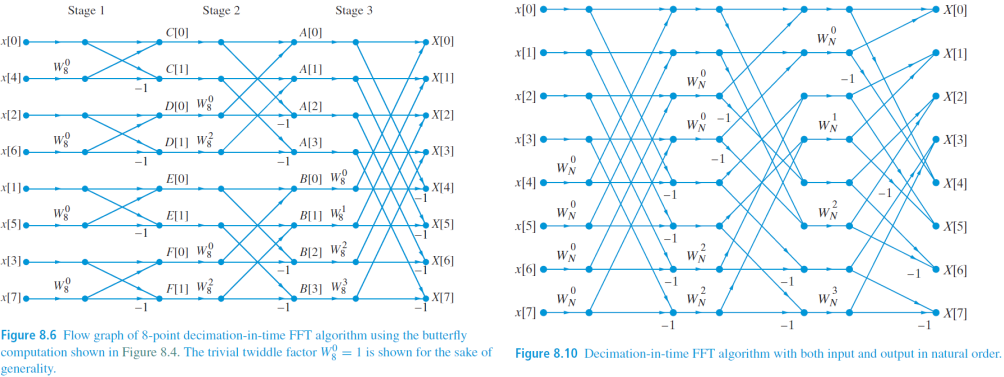

(a) Express $s_m \left\lbrack k\right\rbrack$ in terms of $s_{m-1} \left\lbrack k\right\rbrack$ for m = 1, 2, 3.

Ans. 


$$s_1 \left\lbrack \mathrm{k1}\right\rbrack =x\left\lbrack \mathrm{k1}\right\rbrack +x\left\lbrack \mathrm{k1}+4\right\rbrack ,s_1 \left\lbrack \mathrm{k1}+4\right\rbrack =x\left\lbrack \mathrm{k1}\right\rbrack -x\left\lbrack \mathrm{k1}+4\right\rbrack ,\mathrm{k1}=0,1,2,3$$



$$s_2 \left\lbrack \mathrm{k2}\right\rbrack =s_1 \left\lbrack \mathrm{k2}\right\rbrack +s_1 \left\lbrack \mathrm{k2}+2\right\rbrack ,s_2 \left\lbrack \mathrm{k2}+2\right\rbrack =s_1 \left\lbrack \mathrm{k2}+4\right\rbrack +W_8^2 s_1 \left\lbrack \mathrm{k2}+6\right\rbrack ,$$



$$s_2 \left\lbrack \mathrm{k2}+4\right\rbrack =s_1 \left\lbrack \mathrm{k2}\right\rbrack -s_1 \left\lbrack \mathrm{k2}+2\right\rbrack ,s_2 \left\lbrack \mathrm{k2}+6\right\rbrack =s_1 \left\lbrack \mathrm{k2}+4\right\rbrack -W_8^2 s_1 \left\lbrack \mathrm{k2}+6\right\rbrack ,\;\mathrm{k2}=0,1$$



$$s_3 \left\lbrack 0\right\rbrack =s_2 \left\lbrack 0\right\rbrack +s_2 \left\lbrack 1\right\rbrack ,s_3 \left\lbrack 1\right\rbrack =s_2 \left\lbrack 2\right\rbrack +W_8^1 s_2 \left\lbrack 3\right\rbrack ,s_3 \left\lbrack 2\right\rbrack =s_2 \left\lbrack 4\right\rbrack +W_8^2 s_2 \left\lbrack 5\right\rbrack ,s_3 \left\lbrack 3\right\rbrack =s_2 \left\lbrack 6\right\rbrack +W_8^3 s_2 \left\lbrack 7\right\rbrack$$



$$s_3 \left\lbrack 4\right\rbrack =s_2 \left\lbrack 0\right\rbrack -s_2 \left\lbrack 1\right\rbrack ,s_3 \left\lbrack 5\right\rbrack =s_2 \left\lbrack 2\right\rbrack -W_8^1 s_2 \left\lbrack 3\right\rbrack ,s_3 \left\lbrack 6\right\rbrack =s_2 \left\lbrack 4\right\rbrack -W_8^2 s_2 \left\lbrack 5\right\rbrack ,s_3 \left\lbrack 7\right\rbrack =s_2 \left\lbrack 6\right\rbrack -W_8^3 s_2 \left\lbrack 7\right\rbrack$$


(b) Write a MATLAB function X = fftalt8(x) that computes an 8-point DFT using the equations in part (a). Verify with sequence x[n] = {0,1,2,2,3,3,3,4}. 

close all; clear;
fprintf('3(b)\n');

3(b)



open fftalt8.m;

x = [0 1 2 2 3 3 3 4];
X_fft = fft(x,8)

X_fft =   18.0000 + 0.0000i  -3.0000 + 3.8284i  -2.0000 + 2.0000i  -3.0000 + 1.8284i  -2.0000 + 0.0000i  -3.0000 - 1.8284i  -2.0000 - 2.0000i  -3.0000 - 3.8284i


X_fftalt8 = fftalt8(x)

X_fftalt8 =   18.0000 + 0.0000i  -3.0000 + 3.8284i  -2.0000 + 2.0000i  -3.0000 + 1.8284i  -2.0000 + 0.0000i  -3.0000 - 1.8284i  -2.0000 - 2.0000i  -3.0000 - 3.8284i


(c) Compare the coding complexity of the above function with that of MATLAB function fftditr2 shown in Figure 8.6, and comment on its usefulness. 

close all; clear;
fprintf('3(c)\n');

3(c)


x = [0 1 2 2 3 3 3 4];
X_fftditr2 = fftditr2(x)

X_fftditr2 =   18.0000 + 0.0000i  -3.0000 + 3.8284i  -2.0000 + 2.0000i  -3.0000 + 1.8284i  -2.0000 + 0.0000i  -3.0000 - 1.8284i  -2.0000 - 2.0000i  -3.0000 - 3.8284i


(Comment) 

就 coding complexity 而言，fftalt8 顯得複雜，因為需要將前一級算完才能算下一級，而且架構相對 fftditr2 複雜，沒辦法像 fftditr2 用三層 for 迴圈就完成此 function，因次在 coding 的複雜度方面也就比 fftditr2 複雜。

## P4

Using the flow graph of Figure 8.13 and following the approach used in developing the fftditr2 function. 

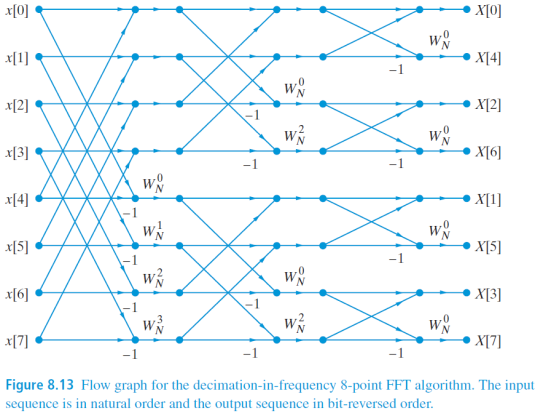

(a) Develop a radix-2 DIF-FFT function X = fftdifr2(x) for power-of-2 length N.

close all; clear;
fprintf('4(a)\n');

4(a)



open fftdifr2.m;

(b) Verify your function for N = $2^v$, where 2 ≤ ν ≤ 10. For this purpose generate an N-point complex-valued signal as x = randn(1,N) + 1j*randn(1,N). 

fprintf('4(b)\n');

4(b)



for v = 2:10
    N = 2^v;
    x = randn(1,N) + 1j*randn(1,N);
    fprintf('for N = 2^%d\n', v);
    X_fftdifr2 = fftdifr2(x)
    X_fft = fft(x)
end

for N = 2^2


X_fftdifr2 =    0.7229 - 0.6519i   1.2888 + 2.2962i   1.1090 - 0.8002i  -1.0473 + 1.9618i


X_fft =    0.7229 - 0.6519i   1.2888 + 2.2962i   1.1090 - 0.8002i  -1.0473 + 1.9618i


for N = 2^3


X_fftdifr2 =   -0.6388 + 1.4476i  -0.6774 + 0.2921i  -0.5768 - 2.3854i  -6.3883 - 2.8715i  -1.4383 + 4.1044i   2.1459 + 3.8796i   1.9645 - 1.0554i  -4.2348 - 7.7138i


X_fft =   -0.6388 + 1.4476i  -0.6774 + 0.2921i  -0.5768 - 2.3854i  -6.3883 - 2.8715i  -1.4383 + 4.1044i   2.1459 + 3.8796i   1.9645 - 1.0554i  -4.2348 - 7.7138i


for N = 2^4


X_fftdifr2 =   -2.8699 + 0.9639i   1.1856 + 1.0836i  -8.4793 - 2.0574i   1.2718 + 5.0888i   0.1619 - 4.7511i  -8.4305 - 2.4848i   3.6832 + 0.0987i  -7.1961 - 0.1224i  -0.1359 + 3.2907i   0.5572 - 3.6978i  -4.0258 - 2.3095i   0.2368 - 1.6964i  -1.6948 - 1.6724i  -6.2349 - 1.7324i  -0.5814 - 3.7126i  -7.8404 - 3.3248i


X_fft =   -2.8699 + 0.9639i   1.1856 + 1.0836i  -8.4793 - 2.0574i   1.2718 + 5.0888i   0.1619 - 4.7511i  -8.4305 - 2.4848i   3.6832 + 0.0987i  -7.1961 - 0.1224i  -0.1359 + 3.2907i   0.5572 - 3.6978i  -4.0258 - 2.3095i   0.2368 - 1.6964i  -1.6948 - 1.6724i  -6.2349 - 1.7324i  -0.5814 - 3.7126i  -7.8404 - 3.3248i


for N = 2^5


X_fftdifr2 =   -6.8237 - 3.9361i  -0.7731 + 3.6484i  -1.3866 - 3.3637i  -0.1640 + 2.3503i   5.6611 + 4.6929i  -9.9273 + 7.6309i   4.3666 - 2.5263i   9.5309 - 4.4049i   1.4753 - 5.1204i  -1.6684 + 3.6186i   8.4111 - 5.5795i  -4.5146 + 5.4790i  -7.1423 - 1.5076i  10.0318 - 6.7122i   0.7829 + 7.6427i   3.3647 + 2.7505i  -4.4639 - 5.7693i   7.9436 + 5.7740i  -0.1367 - 1.3968i  -7.5027 - 6.3077i  -3.9457 + 9.1941i  -1.1974 - 7.4356i  -2.1641 + 4.3190i   0.9726 -10.0878i  -0.2292 -11.2149i   6.5258 + 7.0324i   6.0527 + 2.2503i  -0.4033 - 1.2616i  -7.4594 + 6.2693i  -5.4782 + 7.0991i   0.3969 - 2.1189i  -9.8059 + 2.0657i


X_fft =   -6.8237 - 3.9361i  -0.7731 + 3.6484i  -1.3866 - 3.3637i  -0.1640 + 2.3503i   5.6611 + 4.6929i  -9.9273 + 7.6309i   4.3666 - 2.5263i   9.5309 - 4.4049i   1.4753 - 5.1204i  -1.6684 + 3.6186i   8.4111 - 5.5795i  -4.5146 + 5.4790i  -7.1423 - 1.5076i  10.0318 - 6.7122i   0.7829 + 7.6427i   3.3647 + 2.7505i  -4.4639 - 5.7693i   7.9436 + 5.7740i  -0.1367 - 1.3968i  -7.5027 - 6.3077i  -3.9457 + 9.1941i  -1.1974 - 7.4356i  -2.1641 + 4.3190i   0.9726 -10.0878i  -0.2292 -11.2149i   6.5258 + 7.0324i   6.0527 + 2.2503i  -0.4033 - 1.2616i  -7.4594 + 6.2693i  -5.4782 + 7.0991i   0.3969 - 2.1189i  -9.8059 + 2.0657i


for N = 2^6


X_fftdifr2 =    8.4193 + 3.7853i   1.2007 + 8.2331i   6.2577 + 2.3820i  -0.9565 - 5.1766i  -2.9088 - 6.4556i -12.1521 +17.8408i  -3.5846 - 0.6996i  -3.4578 -11.7529i   0.6565 +11.7073i   3.4815 - 3.1105i  12.0916 +20.4243i  -5.2393 +14.9561i   4.3994 - 7.9099i   2.3937 + 3.7526i  13.5808 + 8.3156i   4.0772 -14.2933i  -3.1192 - 3.2801i   7.3413 -11.8819i  -8.1184 + 4.1415i   3.3259 - 8.9621i  14.2932 + 3.2066i  15.2976 - 1.7816i   1.3636 - 0.1673i   0.6742 + 3.7152i -11.2084 - 0.5228i  -9.6623 + 3.5464i -10.7430 - 1.3931i  -0.5078 - 1.4330i   6.5138 - 3.3329i  -8.2236 - 2.9261i   0.3156 - 3.3182i  12.3460 + 3.2986i  -8.9154 -17.6951i   0.0379 - 1.2990i   8.4940 + 1.4641i  -0.7633 + 4.3525i  -0.4029 + 1.2705i   5.7625 - 3.7379i   0.8469 - 2.9660i  -6.2649 + 2.3292i   3.1321 - 2.9089i -12.5208 +16.0033i   8.3798 +10.8033i   4.4958 + 0.3719i   0.2602 + 0.8249i  17.4491 -10.0283i  14.9710 -22.3886i  -8.8829 + 5.3162i   2.1836 +11.2953i  12.8310 + 3.7149i


X_fft =    8.4193 + 3.7853i   1.2007 + 8.2331i   6.2577 + 2.3820i  -0.9565 - 5.1766i  -2.9088 - 6.4556i -12.1521 +17.8408i  -3.5846 - 0.6996i  -3.4578 -11.7529i   0.6565 +11.7073i   3.4815 - 3.1105i  12.0916 +20.4243i  -5.2393 +14.9561i   4.3994 - 7.9099i   2.3937 + 3.7526i  13.5808 + 8.3156i   4.0772 -14.2933i  -3.1192 - 3.2801i   7.3413 -11.8819i  -8.1184 + 4.1415i   3.3259 - 8.9621i  14.2932 + 3.2066i  15.2976 - 1.7816i   1.3636 - 0.1673i   0.6742 + 3.7152i -11.2084 - 0.5228i  -9.6623 + 3.5464i -10.7430 - 1.3931i  -0.5078 - 1.4330i   6.5138 - 3.3329i  -8.2236 - 2.9261i   0.3156 - 3.3182i  12.3460 + 3.2986i  -8.9154 -17.6951i   0.0379 - 1.2990i   8.4940 + 1.4641i  -0.7633 + 4.3525i  -0.4029 + 1.2705i   5.7625 - 3.7379i   0.8469 - 2.9660i  -6.2649 + 2.3292i   3.1321 - 2.9089i -12.5208 +16.0033i   8.3798 +10.8033i   4.4958 + 0.3719i   0.2602 + 0.8249i  17.4491 -10.0283i  14.9710 -22.3886i  -8.8829 + 5.3162i   2.1836 +11.2953i  12.8310 + 3.7149i


for N = 2^7


X_fftdifr2 =   -8.2014 - 8.0684i  -0.6122 + 2.5266i -28.2804 - 9.0278i  11.8084 + 6.1246i  -2.3735 - 1.9331i  12.6877 -21.5308i  21.5213 - 7.5567i -14.0198 -13.7147i   2.2153 + 9.9937i  -9.4911 - 2.9959i -17.0344 - 1.6350i  -5.2571 + 1.1647i -10.8668 -16.9232i -33.4793 -24.9874i  -6.6928 -21.1947i   7.4131 + 5.5384i  -6.1125 +14.5758i   3.2867 + 1.0285i  -2.7732 - 9.0110i  -1.4341 + 3.6182i   4.4096 + 2.6043i  16.5754 + 0.1240i -17.6021 + 1.2232i   5.6908 - 3.8077i   8.8967 - 4.9174i -10.1034 + 3.3580i  10.7952 +10.8556i   6.5715 - 2.3846i  -9.1447 -19.8175i  -7.6770 - 3.0486i -24.6980 -19.0483i -11.3014 -13.0960i   4.1893 -17.6765i  -9.7322 - 1.3881i  13.1802 - 9.8530i  10.5859 - 7.5253i  -0.8152 + 0.1883i   3.8191 +16.5627i  18.4902 -15.3988i   7.9051 -15.6571i  14.5871 -18.3099i   2.3290 - 8.6706i  -3.2436 - 6.2563i -19.7302 + 0.7068i   3.7942 +23.2670i  -1.4470 - 0.7782i  -1.7089 - 1.5889i   7.1999 +25.1596i   1.2457 + 4.1967i  -1.9669 - 5.5337i


X_fft =   -8.2014 - 8.0684i  -0.6122 + 2.5266i -28.2804 - 9.0278i  11.8084 + 6.1246i  -2.3735 - 1.9331i  12.6877 -21.5308i  21.5213 - 7.5567i -14.0198 -13.7147i   2.2153 + 9.9937i  -9.4911 - 2.9959i -17.0344 - 1.6350i  -5.2571 + 1.1647i -10.8668 -16.9232i -33.4793 -24.9874i  -6.6928 -21.1947i   7.4131 + 5.5384i  -6.1125 +14.5758i   3.2867 + 1.0285i  -2.7732 - 9.0110i  -1.4341 + 3.6182i   4.4096 + 2.6043i  16.5754 + 0.1240i -17.6021 + 1.2232i   5.6908 - 3.8077i   8.8967 - 4.9174i -10.1034 + 3.3580i  10.7952 +10.8556i   6.5715 - 2.3846i  -9.1447 -19.8175i  -7.6770 - 3.0486i -24.6980 -19.0483i -11.3014 -13.0960i   4.1893 -17.6765i  -9.7322 - 1.3881i  13.1802 - 9.8530i  10.5859 - 7.5253i  -0.8152 + 0.1883i   3.8191 +16.5627i  18.4902 -15.3988i   7.9051 -15.6571i  14.5871 -18.3099i   2.3290 - 8.6706i  -3.2436 - 6.2563i -19.7302 + 0.7068i   3.7942 +23.2670i  -1.4470 - 0.7782i  -1.7089 - 1.5889i   7.1999 +25.1596i   1.2457 + 4.1967i  -1.9669 - 5.5337i


for N = 2^8


X_fftdifr2 =  -21.3933 -25.0174i -10.1746 +18.1729i  -7.8854 -12.4340i  -8.2055 +37.9570i   4.0764 + 5.3076i -17.4536 +18.3762i -15.7539 - 7.6762i  18.0979 -16.1037i -21.3006 -18.6108i -10.5201 + 8.1835i  -4.3617 + 0.5511i  -6.3836 -22.8514i  26.7094 + 6.8833i  12.9211 +10.3357i   1.8605 + 9.1057i -14.2595 + 3.6603i   4.6448 - 7.1133i  15.3207 +15.4206i   8.7702 + 9.6733i   3.3717 -14.5293i -18.8070 +13.6977i  -5.0494 - 4.1448i -14.1470 +10.3226i -11.6903 -22.3061i   8.4665 +17.8278i  -4.3035 + 9.2928i -35.7794 +32.2039i   9.5489 -19.4585i  -5.2010 -10.7387i  -7.8066 -15.3155i   7.6117 +11.5199i   4.7271 -12.4785i -12.2043 -34.1398i  -3.1366 - 8.0394i  14.3597 +26.9357i -11.5777 -10.8997i -19.3487 + 0.8792i -18.4243 - 2.9685i   5.6560 - 1.3870i   0.8485 +30.6487i  -7.9025 +15.9699i  -7.9041 - 1.2603i  11.7880 +11.8250i   3.5990 -33.9869i  15.0284 -18.9572i  -5.8359 +10.6079i  31.3915 + 9.3163i  -3.6141 + 3.7086i  34.5709 - 6.0324i  -0.0476 - 0.1533i


X_fft =  -21.3933 -25.0174i -10.1746 +18.1729i  -7.8854 -12.4340i  -8.2055 +37.9570i   4.0764 + 5.3076i -17.4536 +18.3762i -15.7539 - 7.6762i  18.0979 -16.1037i -21.3006 -18.6108i -10.5201 + 8.1835i  -4.3617 + 0.5511i  -6.3836 -22.8514i  26.7094 + 6.8833i  12.9211 +10.3357i   1.8605 + 9.1057i -14.2595 + 3.6603i   4.6448 - 7.1133i  15.3207 +15.4206i   8.7702 + 9.6733i   3.3717 -14.5293i -18.8070 +13.6977i  -5.0494 - 4.1448i -14.1470 +10.3226i -11.6903 -22.3061i   8.4665 +17.8278i  -4.3035 + 9.2928i -35.7794 +32.2039i   9.5489 -19.4585i  -5.2010 -10.7387i  -7.8066 -15.3155i   7.6117 +11.5199i   4.7271 -12.4785i -12.2043 -34.1398i  -3.1366 - 8.0394i  14.3597 +26.9357i -11.5777 -10.8997i -19.3487 + 0.8792i -18.4243 - 2.9685i   5.6560 - 1.3870i   0.8485 +30.6487i  -7.9025 +15.9699i  -7.9041 - 1.2603i  11.7880 +11.8250i   3.5990 -33.9869i  15.0284 -18.9572i  -5.8359 +10.6079i  31.3915 + 9.3163i  -3.6141 + 3.7086i  34.5709 - 6.0324i  -0.0476 - 0.1533i


for N = 2^9


X_fftdifr2 =   11.7374 +19.2580i  14.1321 -13.5540i   6.5551 +36.2684i   7.7291 - 1.8899i  -5.9365 -31.9807i   3.0188 +16.2815i  10.7699 +75.1079i -25.2365 -60.7864i -12.3603 + 5.2998i  22.2993 -11.8776i -21.4685 - 4.5595i   4.5532 + 7.3988i  -6.1314 -18.9563i   0.5960 -15.0736i -23.3952 + 0.6956i   9.3958 -33.1064i  34.6911 +13.2993i -34.5860 - 7.5669i  11.7634 -29.1856i -23.3138 +15.5234i   3.1379 -15.5559i -33.2967 -25.7505i  27.6569 - 1.1259i   3.9609 +30.6448i -20.0802 -34.6356i  49.9179 +25.0929i  15.4230 +30.6751i  -5.1596 -14.9448i -20.8116 +44.2114i   2.0931 +14.5329i   3.7968 -43.7721i  34.2404 +29.5552i -11.4790 +17.4430i  24.2472 +40.2915i  33.8887 - 2.3355i   8.6277 - 4.5041i  -7.4823 +22.4954i  12.1615 - 0.4172i  26.9107 + 2.2525i -32.7128 -31.5704i  18.9800 +18.4222i  -0.7184 - 2.1099i  17.1986 - 6.1446i  14.8019 +47.1602i  10.8114 +35.3234i  39.6372 + 1.9709i  18.1904 +40.8647i  27.3591 +17.1483i  -7.4917 - 8.7388i  14.8158 +20.6185i


X_fft =   11.7374 +19.2580i  14.1321 -13.5540i   6.5551 +36.2684i   7.7291 - 1.8899i  -5.9365 -31.9807i   3.0188 +16.2815i  10.7699 +75.1079i -25.2365 -60.7864i -12.3603 + 5.2998i  22.2993 -11.8776i -21.4685 - 4.5595i   4.5532 + 7.3988i  -6.1314 -18.9563i   0.5960 -15.0736i -23.3952 + 0.6956i   9.3958 -33.1064i  34.6911 +13.2993i -34.5860 - 7.5669i  11.7634 -29.1856i -23.3138 +15.5234i   3.1379 -15.5559i -33.2967 -25.7505i  27.6569 - 1.1259i   3.9609 +30.6448i -20.0802 -34.6356i  49.9179 +25.0929i  15.4230 +30.6751i  -5.1596 -14.9448i -20.8116 +44.2114i   2.0931 +14.5329i   3.7968 -43.7721i  34.2404 +29.5552i -11.4790 +17.4430i  24.2472 +40.2915i  33.8887 - 2.3355i   8.6277 - 4.5041i  -7.4823 +22.4954i  12.1615 - 0.4172i  26.9107 + 2.2525i -32.7128 -31.5704i  18.9800 +18.4222i  -0.7184 - 2.1099i  17.1986 - 6.1446i  14.8019 +47.1602i  10.8114 +35.3234i  39.6372 + 1.9709i  18.1904 +40.8647i  27.3591 +17.1483i  -7.4917 - 8.7388i  14.8158 +20.6185i


for N = 2^10


X_fftdifr2 = 	1.0e+02 *

   0.2291 - 0.4560i   0.0540 - 0.0919i  -0.1695 - 0.2888i  -0.2992 - 0.1905i   0.0899 + 0.0693i   0.2113 + 0.1071i  -0.2278 + 0.2324i   0.3475 + 0.3057i  -0.0956 - 0.0468i   0.2148 - 0.0973i  -0.8891 - 0.2627i   0.4512 + 0.1965i   0.1221 + 0.7020i  -0.3202 - 0.1417i   0.1414 + 0.0927i   0.6490 + 0.1329i   0.0296 + 0.2317i  -0.2229 + 0.0235i   0.0069 - 0.6728i  -0.5010 + 0.0940i   0.0953 + 0.0569i  -0.1545 + 0.0963i   0.2559 + 0.1215i   0.0712 - 0.3873i  -0.0079 - 0.1169i   0.0364 - 0.3020i  -0.7683 - 0.3013i  -0.1718 - 0.3518i  -0.4225 + 0.5301i  -0.5112 + 0.1746i  -0.1699 + 0.0344i  -0.2514 + 0.0396i   0.0825 - 0.0054i  -0.3371 + 0.0656i   0.2687 + 0.0399i   0.0635 - 0.2271i  -0.1550 - 0.0719i  -0.0692 - 0.0571i  -0.1698 - 0.0292i  -0.3908 + 0.1962i  -0.0941 + 0.1569i  -0.1526 + 0.5035i  -0.1734 + 0.3671i  -0.2471 + 0.3996i   0.4225 - 0.4357i  -0.4659 - 0.0203i  -0.7440 + 0.3946i  -0.4442 - 0.7051i  -0.0134 - 0.1844i   0.1800 + 0.2977i


X_fft = 	1.0e+02 *

   0.2291 - 0.4560i   0.0540 - 0.0919i  -0.1695 - 0.2888i  -0.2992 - 0.1905i   0.0899 + 0.0693i   0.2113 + 0.1071i  -0.2278 + 0.2324i   0.3475 + 0.3057i  -0.0956 - 0.0468i   0.2148 - 0.0973i  -0.8891 - 0.2627i   0.4512 + 0.1965i   0.1221 + 0.7020i  -0.3202 - 0.1417i   0.1414 + 0.0927i   0.6490 + 0.1329i   0.0296 + 0.2317i  -0.2229 + 0.0235i   0.0069 - 0.6728i  -0.5010 + 0.0940i   0.0953 + 0.0569i  -0.1545 + 0.0963i   0.2559 + 0.1215i   0.0712 - 0.3873i  -0.0079 - 0.1169i   0.0364 - 0.3020i  -0.7683 - 0.3013i  -0.1718 - 0.3518i  -0.4225 + 0.5301i  -0.5112 + 0.1746i  -0.1699 + 0.0344i  -0.2514 + 0.0396i   0.0825 - 0.0054i  -0.3371 + 0.0656i   0.2687 + 0.0399i   0.0635 - 0.2271i  -0.1550 - 0.0719i  -0.0692 - 0.0571i  -0.1698 - 0.0292i  -0.3908 + 0.1962i  -0.0941 + 0.1569i  -0.1526 + 0.5035i  -0.1734 + 0.3671i  -0.2471 + 0.3996i   0.4225 - 0.4357i  -0.4659 - 0.0203i  -0.7440 + 0.3946i  -0.4442 - 0.7051i  -0.0134 - 0.1844i   0.1800 + 0.2977i


(Comment)

由上述結果我們發現 x 經過 fftdifr2 和 fft 得到的結果相同。

## P5

The filterfirdf implements the FIR direct form structure.

(a) Develop a new MATLAB function y=filterfirlp(h,x) that implements the FIR linear-phase form given its impulse response in h. This function should first check if h is one of type-I through type-IV and then simulate the corresponding equations. If h does not correspond to one of the four types then the function should display an appropriate error message. 

Ams.

For Type I: $y\left\lbrack n\right\rbrack =\sum_{k=0}^{\frac{M}{2}-1} h\left\lbrack k\right\rbrack \left(x\left\lbrack n-k\right\rbrack +x\left\lbrack n-M+k\right\rbrack \right)+h\left\lbrack \frac{M}{2}\right\rbrack x\left\lbrack n-\frac{M}{2}\right\rbrack$

For Type II: $y\left\lbrack n\right\rbrack =\sum_{k=0}^{\frac{M-1}{2}} h\left\lbrack k\right\rbrack \left(x\left\lbrack n-k\right\rbrack +x\left\lbrack n-M+k\right\rbrack \right)$

For Type III: $y\left\lbrack n\right\rbrack =\sum_{k=0}^{\frac{M}{2}-1} h\left\lbrack k\right\rbrack \left(x\left\lbrack n-k\right\rbrack -x\left\lbrack n-M+k\right\rbrack \right)$

For Type IV: $y\left\lbrack n\right\rbrack =\sum_{k=0}^{\frac{M-1}{2}} h\left\lbrack k\right\rbrack \left(x\left\lbrack n-k\right\rbrack -x\left\lbrack n-M+k\right\rbrack \right)$

close all; clear;
fprintf('5(a)\n');

5(a)



open filterfirlp.m;

(b) Verify your function on each of the following FIR systems:

h1[n] = {1,2,3,2,1}, h2[n] = {1,-2,3,3,-2,1}, h3[n] = {1,-5,0,5,-1}, h4[n] = {1,-3,-4,4,3,-1}, h5[n] = {1,2,3,-2,-1}, 

For verification determine the first ten samples of the step responses using your function and compare them with those from the filter function. 

fprintf('5(b)\n');

5(b)



x = ones(1, 10);

h1 = [1 2 3 2 1];
[y1, type] = filterfirlp(h1, x)

y1 =      1     3     6     8     9     9     9     9     9     9


type = 'Type I'

y1_verify = filterfirdf(h1, x)

y1_verify =      1     3     6     8     9     9     9     9     9     9



h2 = [1 -2 3 3 -2 1];
[y2, type] = filterfirlp(h2, x)

y2 =      1    -1     2     5     3     4     4     4     4     4


type = 'Type II'

y2_verify = filterfirdf(h2, x)

y2_verify =      1    -1     2     5     3     4     4     4     4     4



h3 = [1 -5 0 5 -1];
[y3, type] = filterfirlp(h3, x)

y3 =      1    -4    -4     1     0     0     0     0     0     0


type = 'Type III'

y3_verify = filterfirdf(h3, x)

y3_verify =      1    -4    -4     1     0     0     0     0     0     0



h4 = [1 -3 -4 4 3 -1];
[y4, type] = filterfirlp(h4, x)

y4 =      1    -2    -6    -2     1     0     0     0     0     0


type = 'Type IV'

y4_verify = filterfirdf(h4, x)

y4_verify =      1    -2    -6    -2     1     0     0     0     0     0



h5 = [1 2 3 -2 -1];
[y5, type] = filterfirlp(h5, x)

y5 =      1     3     6     4     3     3     3     3     3     3


type = 'Not correspond to one of the four types.'

y5_verify = filterfirdf(h5, x)

y5_verify =      1     3     6     4     3     3     3     3     3     3


## P6

Consider the IIR normal direct form II structure given in Figure 9.6 and implemented by (9.18) and (9.20). 

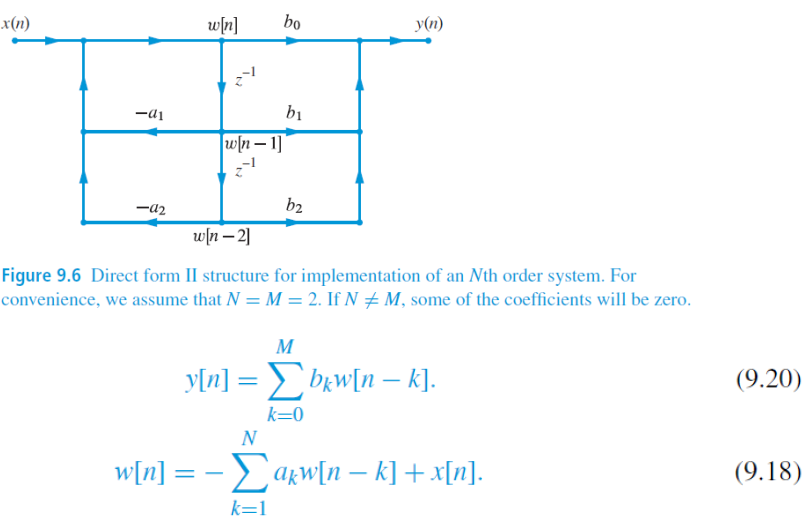

(a) Using the MATLAB function filterdf1 as a guide, develop a MATLAB function y=filterdf2(b,a,x) that implements the normal direct form II structure. Assume zero initial conditions.

close all; clear;
fprintf('6(a)\n');

6(a)



open filterdf2.m;

(b) Determine y[n], 0 ≤ n ≤ 500 using your function and filterdf1 function with following inputs: 


$$x\left\lbrack n\right\rbrack ={\left(\frac{1}{4}\right)}^n u\left\lbrack n\right\rbrack ,a=\left\lbrack \begin{array}{ccc}
1 & -1\ldotp 5 & 0\ldotp 5
\end{array}\right\rbrack ,b=1$$


Compare your results to verify that your filterdf2 function is correctly implemented. 

fprintf('6(b)\n');

6(b)



n = 0:1:500;
x = (1/4).^n; a = [1 -1.5 0.5]; b = [1];
y = filterdf2(b,a,x)'

y =     1.0000    1.7500    2.1875    2.4219    2.5430    2.6045    2.6355    2.6511    2.6589    2.6628    2.6647    2.6657    2.6662    2.6664    2.6665    2.6666    2.6666    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667


y_verify = filterdf1(b,a,x)'

y_verify =     1.0000    1.7500    2.1875    2.4219    2.5430    2.6045    2.6355    2.6511    2.6589    2.6628    2.6647    2.6657    2.6662    2.6664    2.6665    2.6666    2.6666    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667


(Comment)

由上面的結果顯示，從 filterdf1 和 filterdf2 得到的結果相同。

## P7

The following numerator and denominator arrays in MATLAB represent the system function of a discrete-time system in direct form: 

b = [1,-2.61,2.75,-1.36,0.27], a = [1,-1.05,0.91,-0.8,0.38]. 

Determine and draw each of the following structures: 

close all; clear;
fprintf('7\n');

7


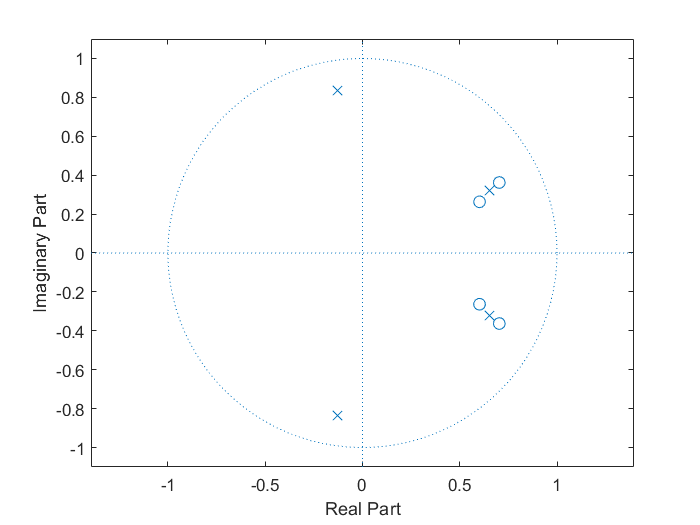

num = [1 -2.61 2.75 -1.36 0.27]; 
den = [1 -1.05 0.91 -0.8 0.38];
figure; zplane(num, den);

[num,den] = eqtflength(num,den);
[zero,pole,k] = tf2zp(num,den)

zero =    0.7033 + 0.3624i
   0.7033 - 0.3624i
   0.6017 + 0.2632i
   0.6017 - 0.2632i


pole =   -0.1288 + 0.8365i
  -0.1288 - 0.8365i
   0.6538 + 0.3210i
   0.6538 - 0.3210i


k = 1

(Comment)


$$H\left(z\right)=\frac{1-2\ldotp 61z^{-1} +2\ldotp 75z^{-2} -1\ldotp 36z^{-3} +0\ldotp 27z^{-4} }{1-1\ldotp 05z^{-1} +0\ldotp 91z^{-2} -0\ldotp 8z^{-3} +0\ldotp 38z^{-4} }=\frac{\left(1+0\ldotp 26z^{-1} +0\ldotp 72z^{-2} \right)\left(1-1\ldotp 31z^{-1} +0\ldotp 53z^{-2} \right)}{\left(1-1\ldotp 41z^{-1} +0\ldotp 63z^{-2} \right)\left(1-1\ldotp 2z^{-1} +0\ldotp 43z^{-2} \right)}$$


(a) Cascade form with second-order sections in normal direct form I, 

Ans. 


$$y\left\lbrack n\right\rbrack =-\sum_{k=1}^N a_k y\left\lbrack n-k\right\rbrack +\sum_{k=0}^M b_k x\left\lbrack n-k\right\rbrack ,H\left(z\right)=\frac{Y\left(z\right)}{X\left(z\right)}=\frac{\sum_{k=0}^M b_k z^{-k} }{1+\sum_{k=1}^N a_k z^{-k} }$$


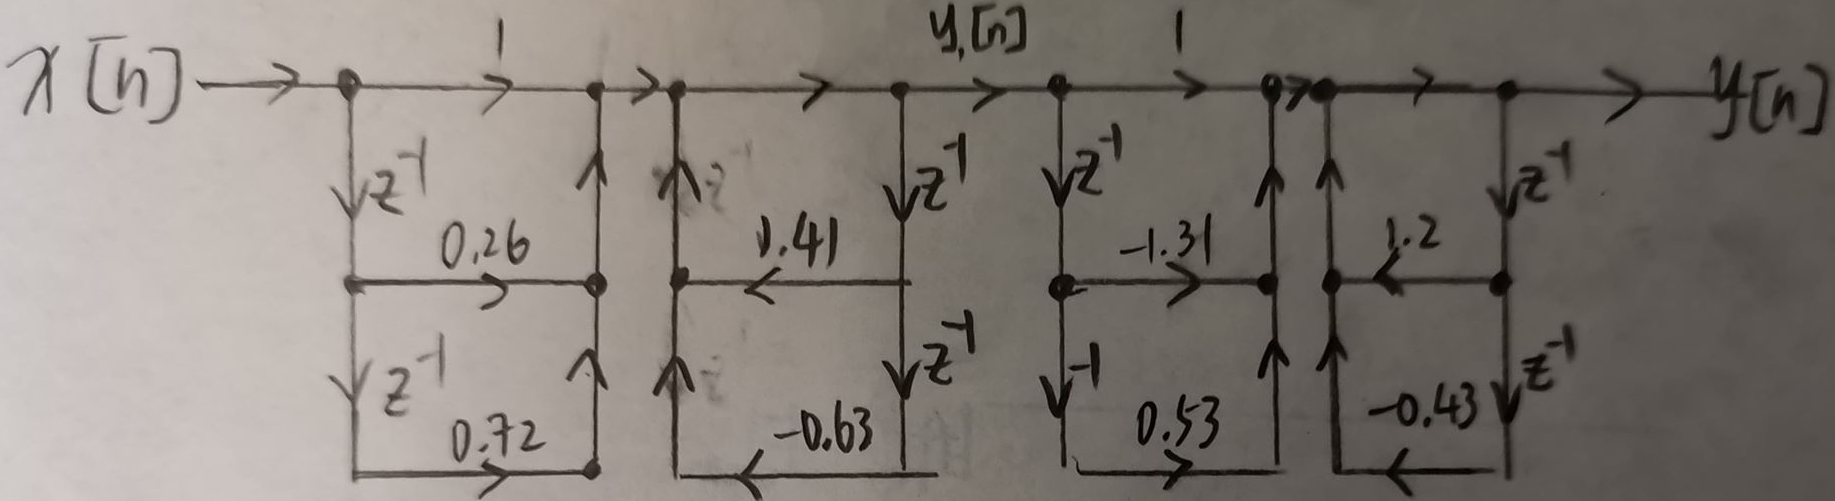

(b) Cascade form with second-order sections in transposed direct form I, 


$$w\left\lbrack n\right\rbrack =-\sum_{k=1}^N a_k w\left\lbrack n-k\right\rbrack +x\left\lbrack n\right\rbrack ,y\left\lbrack n\right\rbrack =\sum_{k=0}^M b_k w\left\lbrack n-k\right\rbrack$$


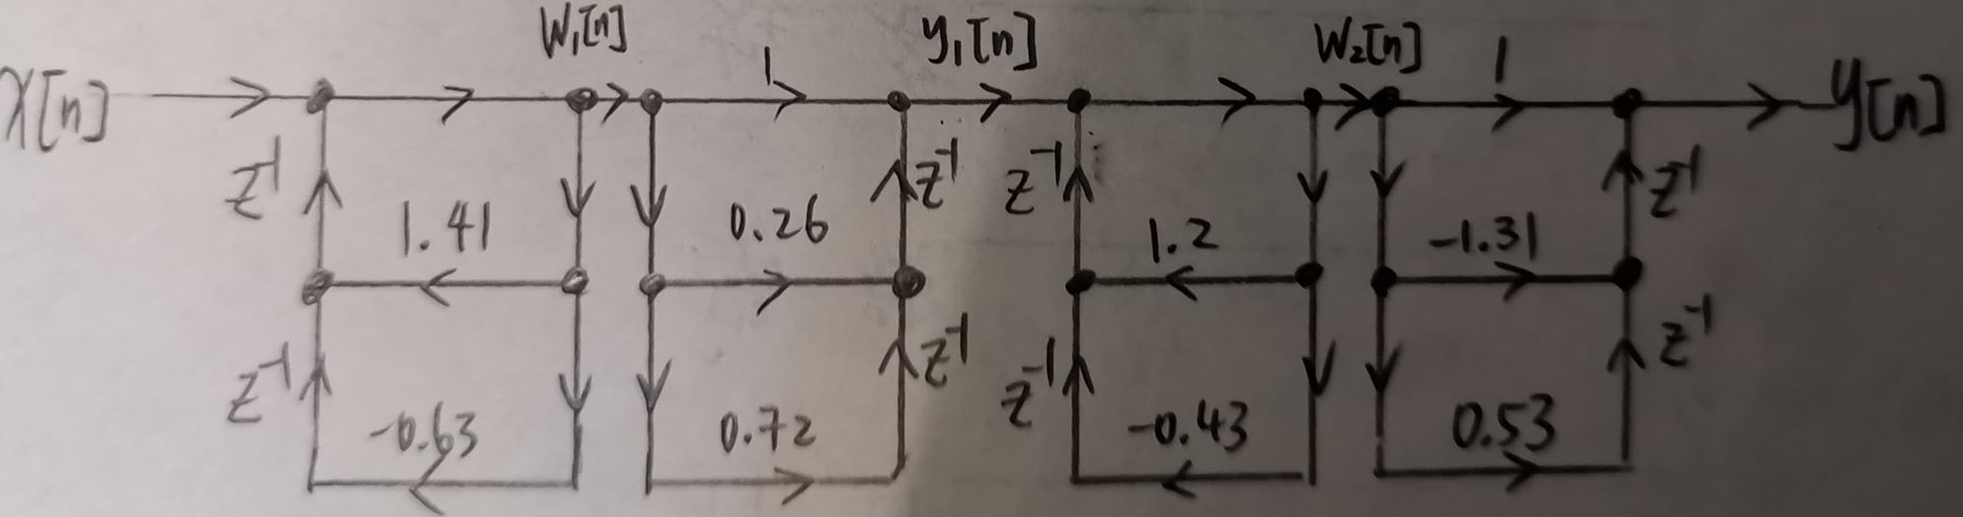

(c) Cascade form with second-order sections in normal direct form II, 


$$W\left(z\right)=\frac{1}{1+\sum_{k=1}^N a_k z^{-k} },Y\left(z\right)=\sum_{k=0}^M b_k z^{-k} W\left(z\right)$$


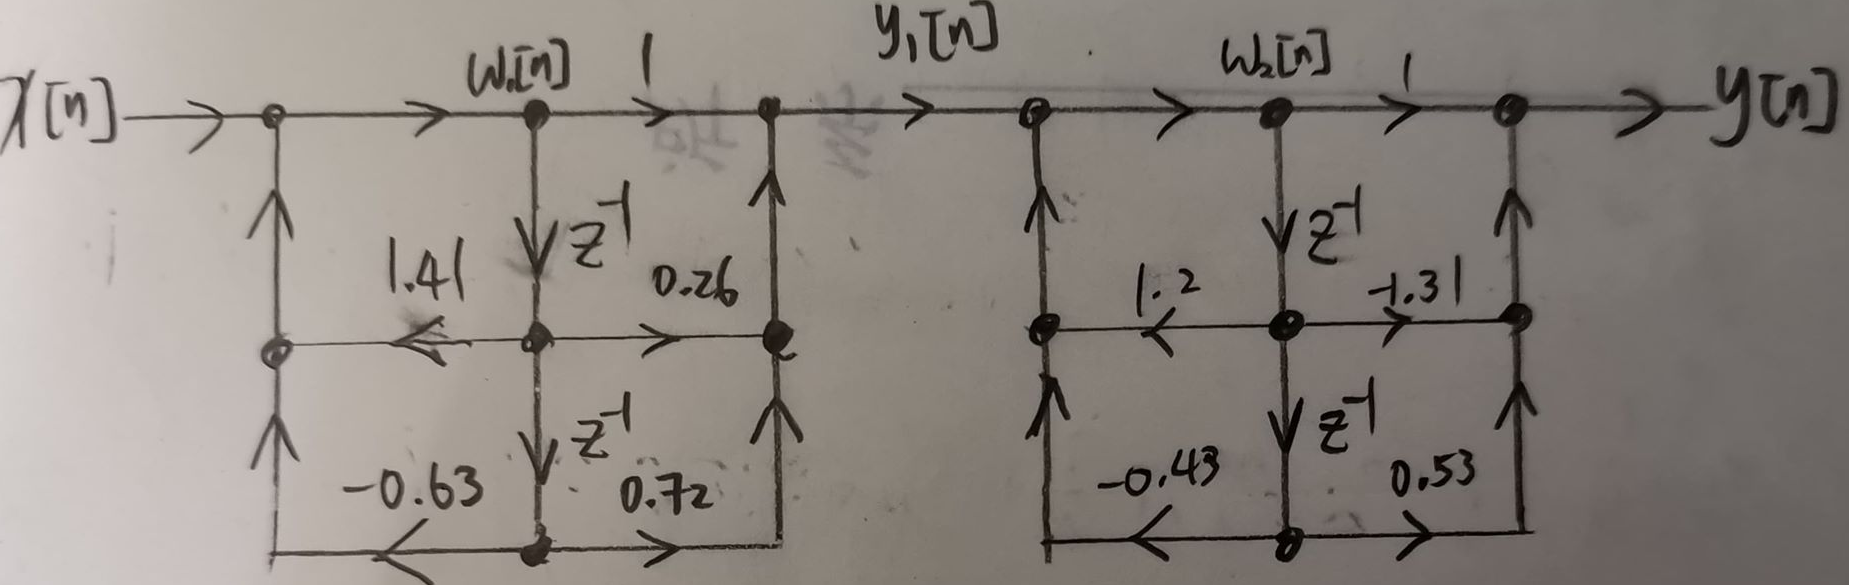

(d) Cascade form with second-order sections in transposed direct form II.


$$\begin{array}{l}
H\left(z\right)=\frac{Y\left(z\right)}{X\left(z\right)}=\frac{b_0 +b_1 z^{-1} +b_2 z^{-2} }{1+a_1 z^{-1} +a_2 z^{-2} },\\
Y\left(z\right)=z^{-1} V_1 \left(z\right)+b_0 X\left(z\right),V_1 \left(z\right)=z^{-1} V_2 \left(z\right)-a_1 Y\left(z\right)+b_1 X\left(z\right),V_2 \left(z\right)=b_2 X\left(z\right)-a_2 Y\left(z\right)
\end{array}$$


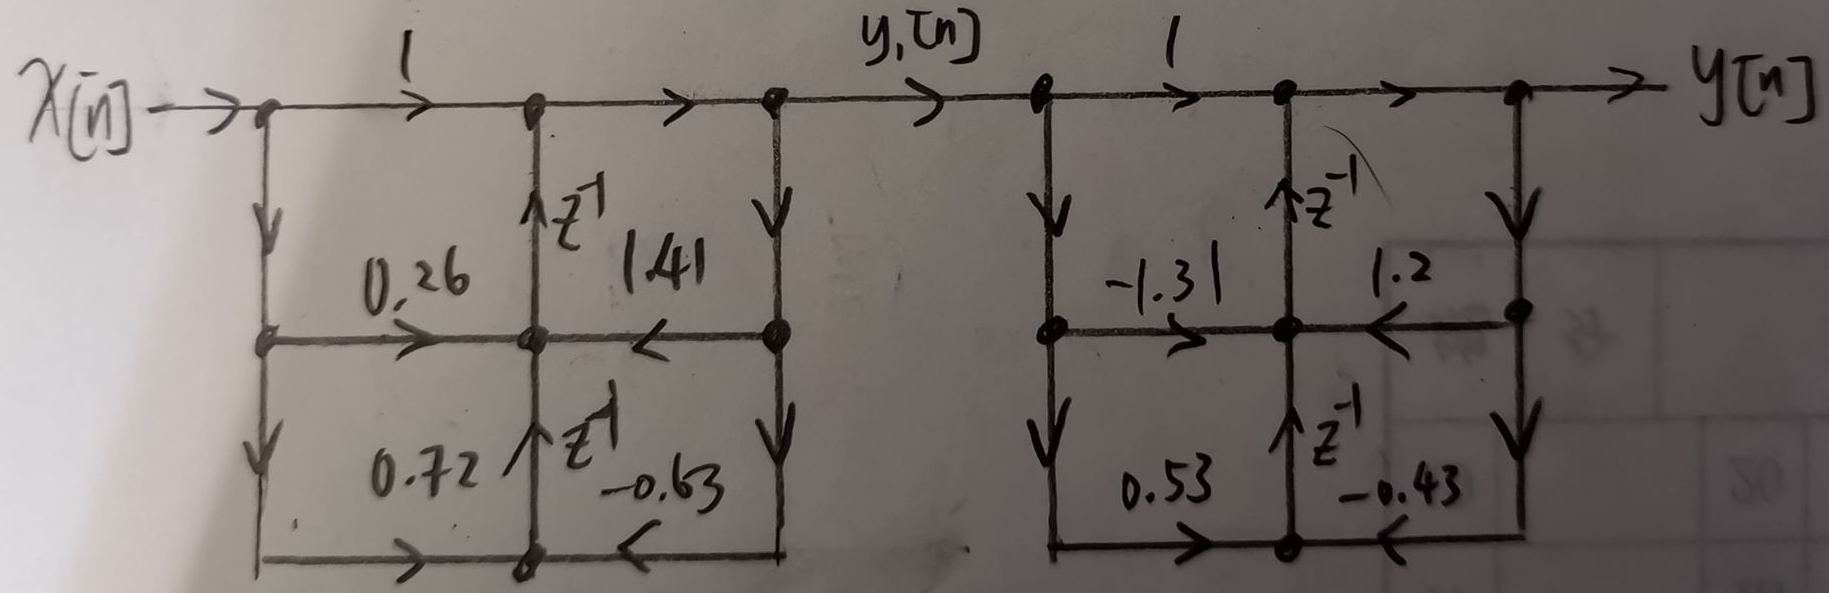

## P8

The frequency-sampling form is developed using (9.50) which uses complex arithmetic. 

$H\left(z\right)=\frac{1-z^{-N} }{N}\sum_{k=0}^{N-1} \frac{H\left\lbrack k\right\rbrack }{1-z^{-1} e^{j\frac{2\pi }{N}k} },H\left\lbrack k\right\rbrack =H\left(z\right)|_{z=e^{j\frac{2\pi }{N}k} }$ (9.50)

(a) Develop a MATLAB function [G,sos]=firdf2fs(h) that determines frequency sampling form parameters given in (9.51) and (9.52) given the impulse response in h. The matrix sos (second order system) should contain second-order section coefficients in the form similar to the tf2sos function while G array should contain the respective gains of second-order sections. Incorporate the coefficients for the H[0] and H[N/2] terms in sos and G arrays. 

$H\left(z\right)=\frac{1-z^{-N} }{N}\left\lbrace \frac{H\left\lbrack 0\right\rbrack }{1-z^{-1} }+\frac{H\left\lbrack \frac{N}{2}\right\rbrack }{1+z^{-1} }+\sum_{k=1}^K 2|H\left\lbrack k\right\rbrack |H_k \left(z\right)\right\rbrace$ (9.51)

$H_k \left(z\right)=\frac{\mathrm{cos}\left(\angle H\left\lbrack k\right\rbrack \right)-z^{-1} \mathrm{cos}\left(\angle H\left\lbrack k\right\rbrack -\frac{2\pi k}{N}\right)}{1-2\mathrm{cos}\left(\frac{2\pi k}{N}\right)z^{-1} +z^{-2} }$ (9.52)

close all; clear;
fprintf('8(a)\n');

8(a)



open firdf2fs.m;

(b) Verify your function by input h with sampled frequency response (9.53) and compare with the system function (9.54) (see example 9.6 in the textbook) 

$H\left\lbrack k\right\rbrack =H\left(e^{j\frac{2\pi }{33}k} \right)=e^{-j\frac{2\pi }{33}k} \times \left\lbrace \begin{array}{cc}
1 & k=0,1,2,31,32\\
0\ldotp 5 & k=3,30\\
0 & \mathrm{otherwise}
\end{array}\right.$ (9.53)

$H\left(z\right)=\frac{1-z^{-33} }{33}\left\lbrack \frac{1}{1-z^{-1} }+\frac{-1\ldotp 99+1\ldotp 99z^{-1} }{1-1\ldotp 964z^{-1} +z^{-2} }+\frac{1\ldotp 964-1\ldotp 964z^{-1} }{1-1\ldotp 857z^{-1} +z^{-2} }+\frac{-1\ldotp 96+1\ldotp 96z^{-1} }{1-1\ldotp 683z^{-1} +z^{-2} }\right\rbrack$ (9.54)

fprintf('8(b)\n');

8(b)


N = 33;
H = zeros(1, 33);
for k = 1:1:33
    if((k==1)||(k==2)||(k==3))
        H(k) = exp((-1*sqrt(-1)*2*pi*(k-1))/N);
    elseif((k==32)||(k==33))
        H(k) = exp((-1*sqrt(-1)*2*pi*(k-1))/N);
    elseif((k==4)||(k==31))
        H(k) = 0.5*(exp((-1*sqrt(-1)*2*pi*(k-1))/N));
    else
        H(k) = 0;
    end
end
h = ifft(H);
[G, sos] = firdf2fs(h);
sos_after = sos;
for a = 1:1:length(G)
    for b = 1:1:3
        sos_after(a,b) = sos_after(a,b)*G(a);
    end
end
sos_after % sos multiplied by the corresponding G factor

sos_after =    1.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i   0.0000 + 0.0000i
   1.9639 + 0.0000i  -1.8567 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i  -1.9639 + 0.0000i   1.0000 + 0.0000i
   1.8567 + 0.0000i  -1.4475 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i  -1.8567 + 0.0000i   1.0000 + 0.0000i
   0.8413 + 0.0000i  -0.4154 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i  -1.6825 + 0.0000i   1.0000 + 0.0000i
  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i  -1.4475 + 0.0000i   1.0000 + 0.0000i
   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i  -1.1601 + 0.0000i   1.0000 + 0.0000i
   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i  -0.8308 + 0.0000i   1.0000 + 0.0000i
   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i  -0.4715 + 0.0000i   1.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 +

由此結果我們可以發現，經由 firdf2fs 處理後的值與 (9.54) 相近，一樣只有前面 4 項有值。